# **Excavation Supported by Cantilevered Sheet Pile Wall**

This example is from file [Excavation Supported by Cantilevered Sheet Pile Wall](https://opensees.berkeley.edu/wiki/index.php?title=Excavation_Supported_by_Cantilevered_Sheet_Pile_Wall) on the OpenSees website.

Note that this model has a bug: it crashes when ``ops.wipe()`` is run again after analysis. OpenSeesPy has the same problem, which is probably a problem with related components inside OpenSees, but the specific cause is unknown.

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

excavationFEM(ops);


  OpenSeesMatlab v3.8.0.1
  OpenSees MEX Interface for MATLAB
  Copyright (c) 2026, By Yexiang Yan

  Type 'help OpenSeesMatlab' in MATLAB for documentation.
  Documentation also available at 
  https://openseesmatlab.readthedocs.io/en/latest/ 

[OpenSees] InitialStateAnalysisWrapper nDmaterial - Written: C.McGann, P.Arduino, P.Mackenzie-Helnwein, U.Washington
[OpenSees] ContactMaterial2D nDmaterial - Written: K.Petek, P.Mackenzie-Helnwein, P.Arduino, U.Washington
[OpenSees] BeamContact2D element - Written: C.McGann, P.Arduino, P.Mackenzie-Helnwein, U.Washington


Plot Model

[OpenSeesMatlab] Model summary
  Nodes: 526
  Beam elements: 21
  Plane elements: 400
  Contact elements: 84


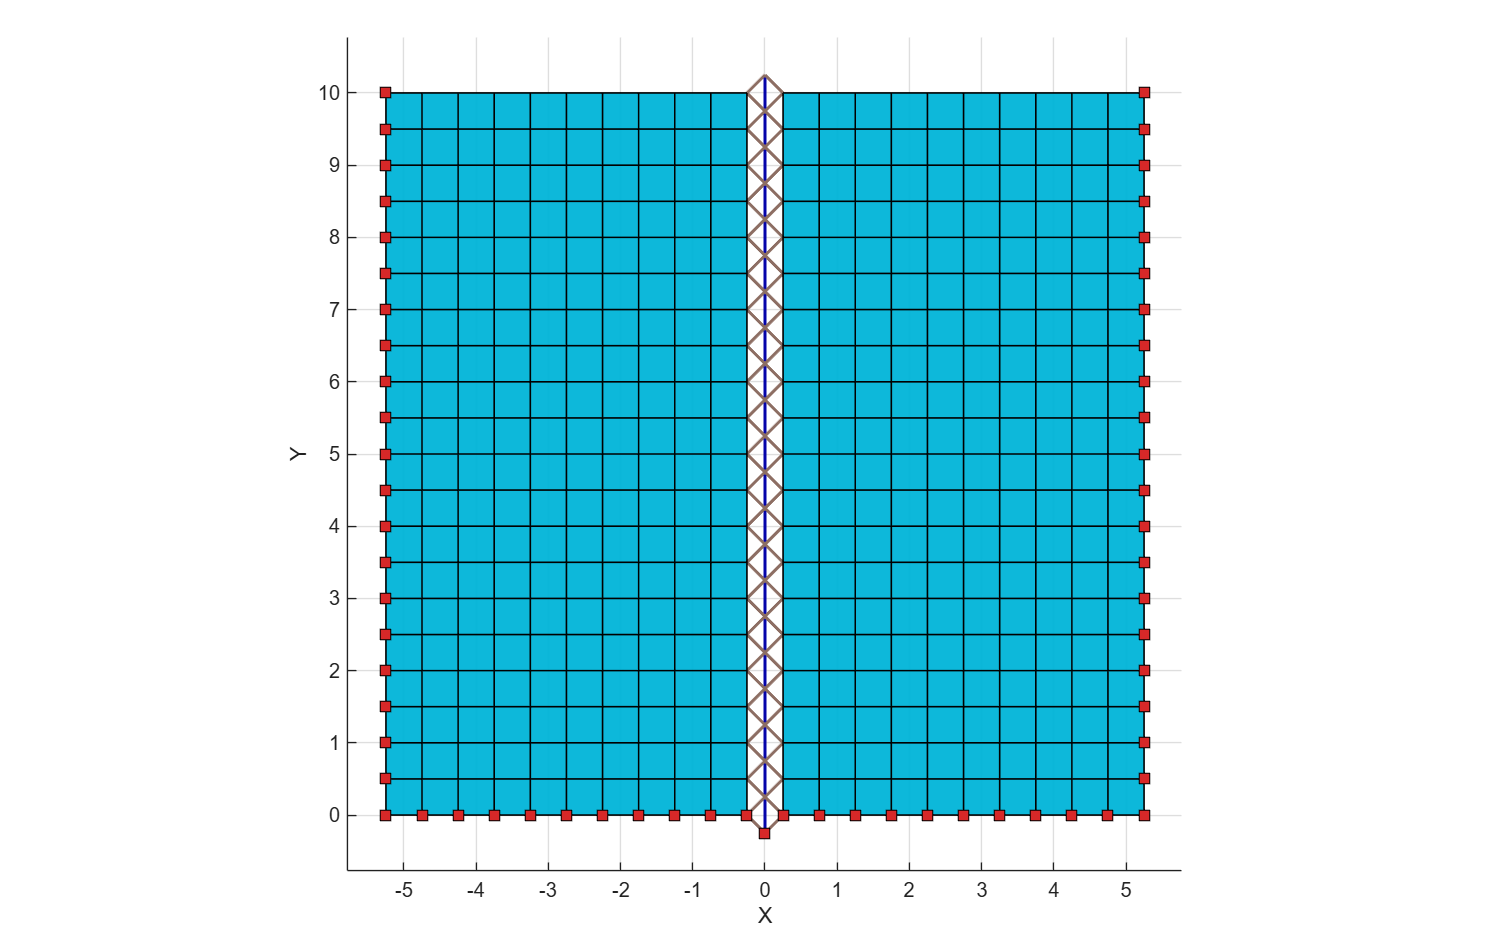

opts = opsMAT.vis.defaultPlotModelOptions;
opts.nodes.showLabels = false;
opsMAT.vis.plotModel(opts=opts);

Create output database (ODB) file. Since some elements and nodes will be removed in subsequent analyses, ensure that `modelUpdate=true`.

ODB = opsMAT.post.createODB("myODB");

ops.constraints("Transformation");
ops.test("NormDispIncr", 1e-05, 50, 0);
ops.algorithm("Newton");
ops.numberer("RCM");
ops.system("BandGeneral");
ops.integrator("LoadControl", 1);
ops.analysis("Static");

ops.InitialStateAnalysis("on");

[OpenSees] InitialStateAnalysis ON


% ensure soil material intially considers linear elastic behavior
ops.updateMaterialStage("-material", 1, "-stage", 0);
% set contact elements to be frictionless for gravity analysis
ops.parameter(1, 'element', 1001, 'friction');
for tag = 1002:1042
    ops.addToParameter(1, 'element', tag);
end
ops.updateParameter(1, 0)

% analysis 4 steps, and fetch response
ops.analyze(4);

% update soil material to consider elastoplastic behavior and analyze a few more steps
ops.updateMaterialStage("-material", 1, "-stage", 1);
% analysis 4 steps, and fetch response
ops.analyze(4);
% designate end of initial state analysis (zeros displacements, keeps state variables)
ops.InitialStateAnalysis("off");

[OpenSees] InitialStateAnalysis OFF
[OpenSees] Domain::addParameter - parameter with tag 0 already exists in model


% turn on frictional behavior for beam contact elements
ops.updateParameter(1, 1)

% define analysis parameters for excavation phase
ops.wipeAnalysis();
ops.constraints("Transformation");
ops.test("NormDispIncr", 0.0001, 60);
ops.algorithm("KrylovNewton");
ops.numberer("RCM");
ops.system("BandGeneral");
ops.integrator("LoadControl", 1);
ops.analysis("Static");

% soil elements
ele_tags = [191, 192, 193, 194, 195, 196, 197, 198, 199, 200];
ele_tags = [ele_tags 1042];  % contact element
% soil nodes
node_tags = [430, 437, 446, 455, 461, 468, 473, 476, 480, 482, 484];
node_tags = [node_tags 1042];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 1 removed")

Lift 1 removed


% remove objects associated with lift 2
% soil elements
ele_tags = [181, 182, 183, 184, 185, 186, 187, 188, 189, 190];
ele_tags = [ele_tags 1040];  % contact element
% soil nodes
node_tags = [412, 424, 433, 444, 453, 460, 466, 471, 475, 479, 483];
node_tags = [node_tags 1040];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 2 removed")

Lift 2 removed



% remove objects associated with lift 3
% soil elements
ele_tags = [171, 172, 173, 174, 175, 176, 177, 178, 179, 180];
ele_tags = [ele_tags 1038];  % contact element
% soil nodes
node_tags = [387, 405, 418, 429, 442, 450, 458, 464, 470, 477, 481];
node_tags = [node_tags 1038];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 3 removed")

Lift 3 removed



% remove objects associated with lift 4
% soil elements
ele_tags = [161, 162, 163, 164, 165, 166, 167, 168, 169, 170];
ele_tags = [ele_tags 1036];  % contact element
% soil nodes
node_tags = [363, 380, 398, 414, 427, 439, 448, 457, 465, 472, 478];
node_tags = [node_tags 1036];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 4 removed")

Lift 4 removed



% remove objects associated with lift 5
% soil elements
ele_tags = [151, 152, 153, 154, 155, 156, 157, 158, 159, 160];
ele_tags = [ele_tags 1034];  % contact element
% soil nodes
node_tags = [336, 353, 378, 395, 411, 425, 440, 449, 459, 467, 474];
node_tags = [node_tags 1034];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 5 removed")

Lift 5 removed



% remove objects associated with lift 6
% soil elements
ele_tags = [141, 142, 143, 144, 145, 146, 147, 148, 149, 150];
ele_tags = [ele_tags 1032];  % contact element
% soil nodes
node_tags = [308, 326, 347, 369, 392, 408, 426, 441, 452, 462, 469];
node_tags = [node_tags 1032];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 6 removed")

Lift 6 removed



% remove objects associated with lift 7
% soil elements
ele_tags = [131, 132, 133, 134, 135, 136, 137, 138, 139, 140];
ele_tags = [ele_tags 1030];  % contact element
% soil nodes
node_tags = [281, 304, 322, 345, 370, 394, 415, 428, 443, 454, 463];
node_tags = [node_tags 1030];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 7 removed")

Lift 7 removed



% remove objects associated with lift 8
% soil elements
ele_tags = [121, 122, 123, 124, 125, 126, 127, 128, 129, 130];
ele_tags = [ele_tags 1028];  % contact element
% soil nodes
node_tags = [260, 278, 302, 325, 346, 374, 399, 419, 434, 447, 456];
node_tags = [node_tags 1028];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 8 removed")

Lift 8 removed




% remove objects associated with lift 9
% soil elements
ele_tags = [111, 112, 113, 114, 115, 116, 117, 118, 119, 120];
ele_tags = [ele_tags 1026];  % contact element
% soil nodes
node_tags = [241, 253, 277, 306, 327, 350, 379, 406, 422, 438, 451];
node_tags = [node_tags 1026];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 9 removed")

Lift 9 removed



% remove objects associated with lift 10
% soil elements
ele_tags = [101, 102, 103, 104, 105, 106, 107, 108, 109, 110];
ele_tags = [ele_tags 1024];  % contact element
% soil nodes
node_tags = [218, 239, 259, 282, 307, 335, 364, 389, 413, 431, 445];
node_tags = [node_tags 1024];  % lagrange multiplier node

for i = 1:numel(ele_tags)
    ops.remove("element", ele_tags(i));
end

for i = 1:numel(node_tags)
    ops.remove("node", node_tags(i));
end

ops.analyze(4);

disp("Lift 10 removed")

Lift 10 removed


odbData = opsMAT.post.getODBData("myODB");

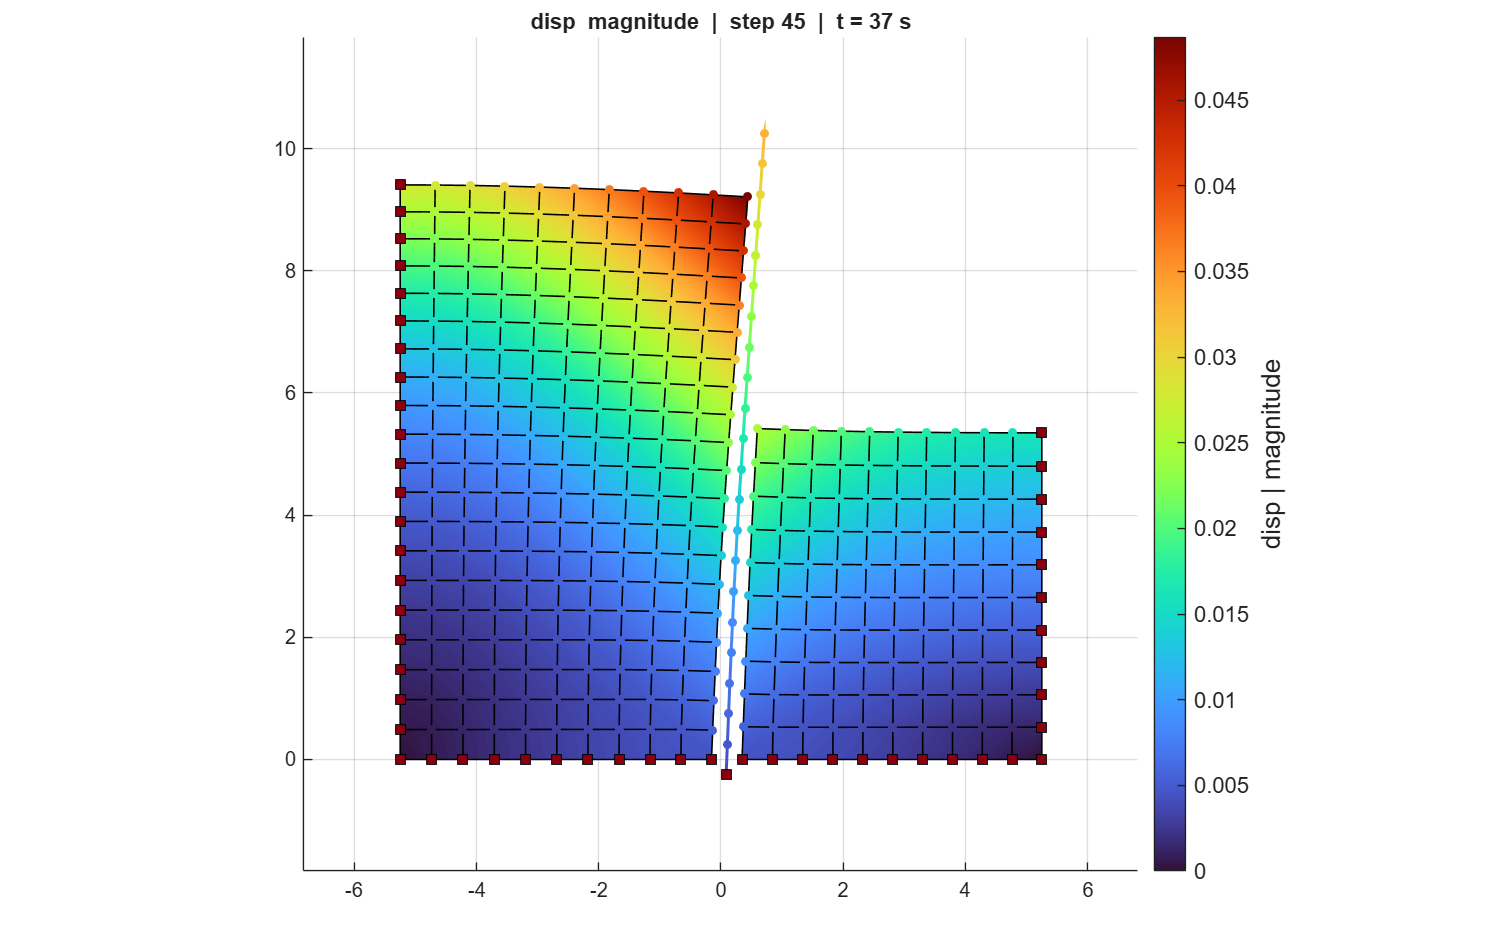

nodeResp = opsMAT.post.getNodalResponse("myODB");

opts=opsMAT.vis.defaultPlotNodalResponseOptions;
opts.nodes.show = true;
opsMAT.vis.plotNodalResponse(nodeResp, stepIdx="absMax", opts=opts);

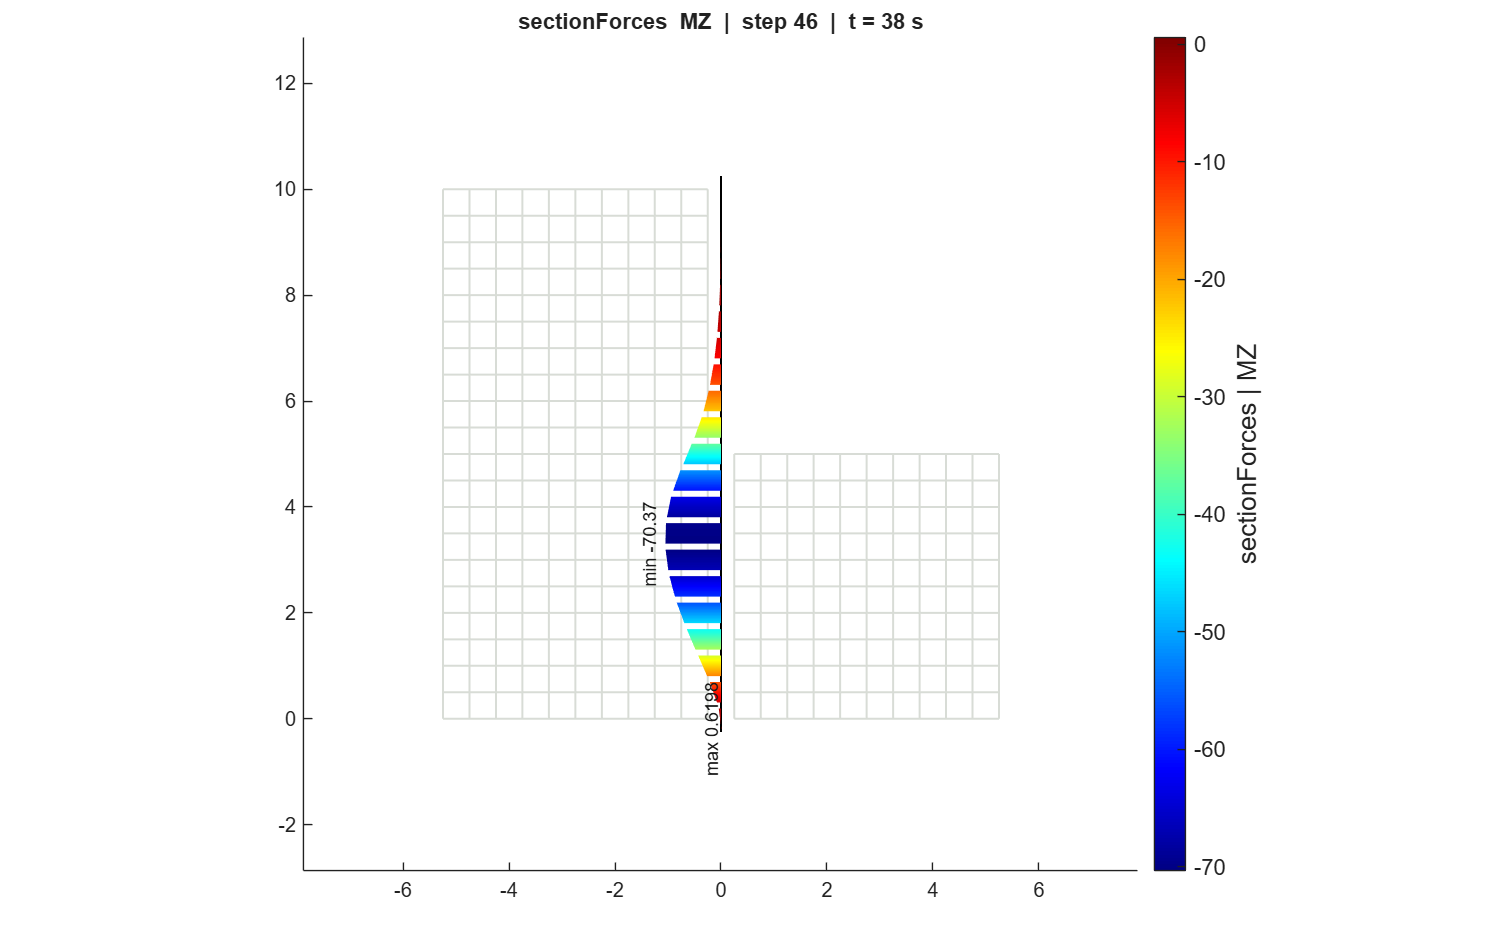

frameResp = opsMAT.post.getElementResponse("myODB", eleType="Frame");

opts = opsMAT.vis.defaultPlotFrameResponseOptions;
opts.showMaxMinLabel = "global";  % 'none' | 'global' | 'element' | 'all'
opts.scale = 2;

opsMAT.vis.plotFrameResponse(frameResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="MZ", opts=opts);
grid off;

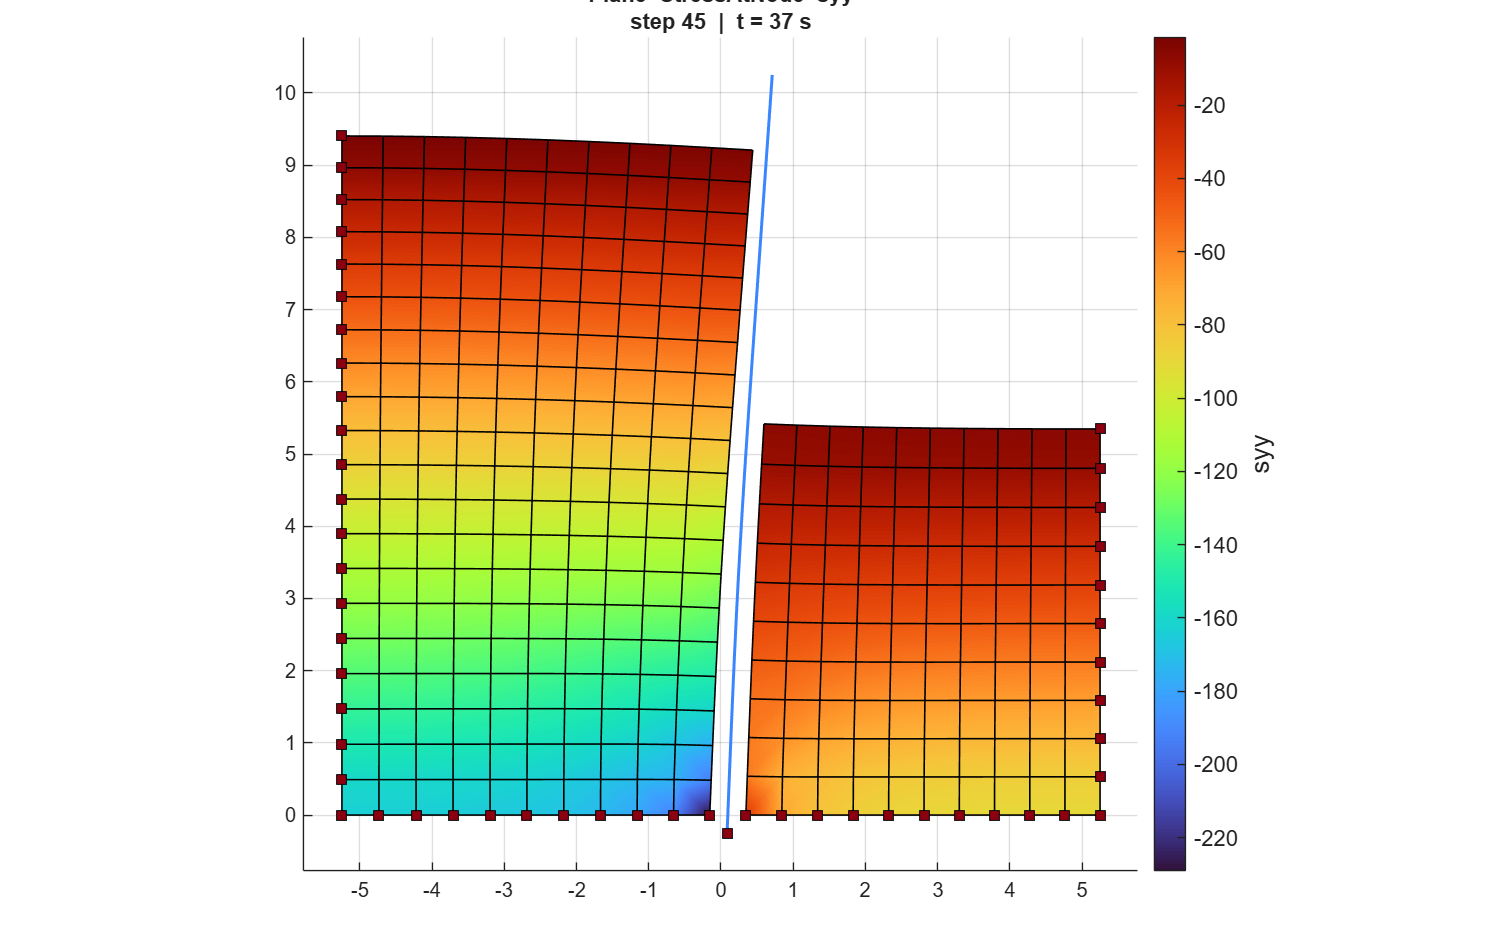

planeResp = opsMAT.post.getElementResponse("myODB", eleType="Plane");

opsMAT.vis.plotContinuumResponse(planeResp, ...
    respType="StressAtNode", respComponent="syy");

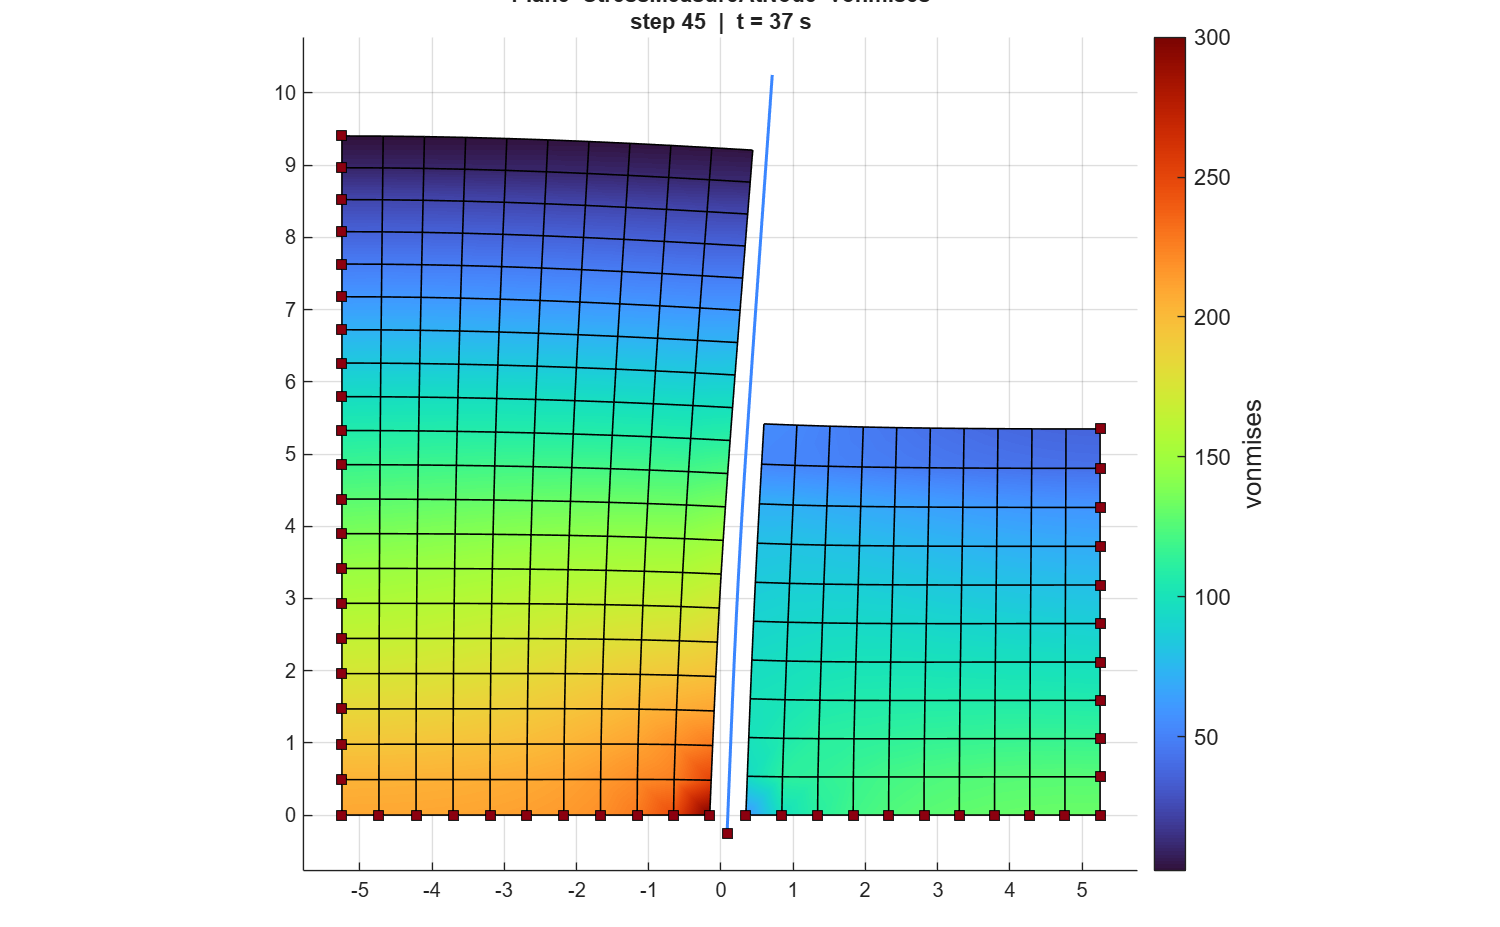

opsMAT.vis.plotContinuumResponse(planeResp, stepIdx="absMax", ...
    respType="StressMeasureAtNode", respComponent="vonMises");

opsMAT.post.writeResponsePVD("myODB");

nodal:         49 steps -> paraview_output/pv_nodal/pv_nodal.pvd
plane:         49 steps -> paraview_output/pv_plane/pv_plane.pvd


![](../utils/paraview-excavation-node-resp.png)

![](../utils/paraview-excavation-plane-resp.png)

function excavationFEM(ops)
    % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % %
    % Excavation of cohesionless soil supported by a cantilevered sheet %
    % pile wall. 2D Plane Strain analysis. Beam elements define the %
    % wall, and beam-contact elements are used to create a frictional %
    % soil-pile interface. Initial state analysis is used to create %
    % an initial state of stress and strain due to gravity without the %
    % corresponding displacements. %
    % %
    % Created by: Chris McGann %
    % Pedro Arduino %
    % --University of Washington-- %
    % %
    % ---> Basic units are kN and m %
    % %
    % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    ops.wipe();
    % -----------------------------------------------------------------------------------------
    % 1. CREATE SOIL NODES AND FIXITIES
    % -----------------------------------------------------------------------------------------
    ops.model("BasicBuilder", "-ndm", 2, "-ndf", 2);
    % define soil nodes
    ops.node(1, -5.25, 0.0);
    ops.node(2, -5.25, 0.5);
    ops.node(3, -4.75, 0.0);
    ops.node(4, -4.75, 0.5);
    ops.node(5, -4.25, 0.0);
    ops.node(6, -5.25, 1.0);
    ops.node(7, -4.75, 1.0);
    ops.node(8, -4.25, 0.5);
    ops.node(9, -4.25, 1.0);
    ops.node(10, -5.25, 1.5);
    ops.node(11, -3.75, 0.0);
    ops.node(12, -4.75, 1.5);
    ops.node(13, -3.75, 0.5);
    ops.node(14, -3.75, 1.0);
    ops.node(15, -4.25, 1.5);
    ops.node(16, -3.25, 0.0);
    ops.node(17, -5.25, 2.0);
    ops.node(18, -4.75, 2.0);
    ops.node(19, -3.25, 0.5);
    ops.node(20, -3.75, 1.5);
    ops.node(21, -3.25, 1.0);
    ops.node(22, -4.25, 2.0);
    ops.node(23, -5.25, 2.5);
    ops.node(24, -2.75, 0.0);
    ops.node(25, -3.25, 1.5);
    ops.node(26, -3.75, 2.0);
    ops.node(27, -4.75, 2.5);
    ops.node(28, -2.75, 0.5);
    ops.node(29, -4.25, 2.5);
    ops.node(30, -2.75, 1.0);
    ops.node(31, -3.25, 2.0);
    ops.node(32, -3.75, 2.5);
    ops.node(33, -2.75, 1.5);
    ops.node(34, -5.25, 3.0);
    ops.node(35, -2.25, 0.0);
    ops.node(36, -4.75, 3.0);
    ops.node(37, -2.25, 0.5);
    ops.node(38, -4.25, 3.0);
    ops.node(39, -2.25, 1.0);
    ops.node(40, -3.25, 2.5);
    ops.node(41, -2.75, 2.0);
    ops.node(42, -3.75, 3.0);
    ops.node(43, -2.25, 1.5);
    ops.node(44, -5.25, 3.5);
    ops.node(45, -1.75, 0.0);
    ops.node(46, -2.75, 2.5);
    ops.node(47, -4.75, 3.5);
    ops.node(48, -1.75, 0.5);
    ops.node(49, -2.25, 2.0);
    ops.node(50, -3.25, 3.0);
    ops.node(51, -1.75, 1.0);
    ops.node(52, -4.25, 3.5);
    ops.node(53, -3.75, 3.5);
    ops.node(54, -1.75, 1.5);
    ops.node(55, -2.25, 2.5);
    ops.node(56, -2.75, 3.0);
    ops.node(57, -5.25, 4.0);
    ops.node(58, -1.25, 0.0);
    ops.node(59, -1.25, 0.5);
    ops.node(60, -4.75, 4.0);
    ops.node(61, -1.75, 2.0);
    ops.node(62, -3.25, 3.5);
    ops.node(63, -4.25, 4.0);
    ops.node(64, -1.25, 1.0);
    ops.node(65, -2.25, 3.0);
    ops.node(66, -3.75, 4.0);
    ops.node(67, -1.25, 1.5);
    ops.node(68, -1.75, 2.5);
    ops.node(69, -2.75, 3.5);
    ops.node(70, -1.25, 2.0);
    ops.node(71, -3.25, 4.0);
    ops.node(72, -0.75, 0.0);
    ops.node(73, -5.25, 4.5);
    ops.node(74, -4.75, 4.5);
    ops.node(75, -0.75, 0.5);
    ops.node(76, -4.25, 4.5);
    ops.node(77, -1.75, 3.0);
    ops.node(78, -2.25, 3.5);
    ops.node(79, -0.75, 1.0);
    ops.node(80, -1.25, 2.5);
    ops.node(81, -2.75, 4.0);
    ops.node(82, -3.75, 4.5);
    ops.node(83, -0.75, 1.5);
    ops.node(84, -0.75, 2.0);
    ops.node(85, -3.25, 4.5);
    ops.node(86, -1.75, 3.5);
    ops.node(87, -5.25, 5.0);
    ops.node(88, -0.25, 0.0);
    ops.node(89, -1.25, 3.0);
    ops.node(90, -2.25, 4.0);
    ops.node(91, -4.75, 5.0);
    ops.node(92, -0.25, 0.5);
    ops.node(93, -0.25, 1.0);
    ops.node(94, -4.25, 5.0);
    ops.node(95, -0.75, 2.5);
    ops.node(96, -2.75, 4.5);
    ops.node(97, -3.75, 5.0);
    ops.node(98, -0.25, 1.5);
    ops.node(102, -1.75, 4.0);
    ops.node(103, -1.25, 3.5);
    ops.node(104, -3.25, 5.0);
    ops.node(105, -0.25, 2.0);
    ops.node(107, -0.75, 3.0);
    ops.node(108, -2.25, 4.5);
    ops.node(109, 0.25, 0.0);
    ops.node(110, -5.25, 5.5);
    ops.node(111, -4.75, 5.5);
    ops.node(112, 0.25, 0.5);
    ops.node(114, -2.75, 5.0);
    ops.node(115, -0.25, 2.5);
    ops.node(116, 0.25, 1.0);
    ops.node(117, -4.25, 5.5);
    ops.node(118, -1.25, 4.0);
    ops.node(119, 0.25, 1.5);
    ops.node(120, -3.75, 5.5);
    ops.node(121, -1.75, 4.5);
    ops.node(122, -0.75, 3.5);
    ops.node(124, -2.25, 5.0);
    ops.node(125, -0.25, 3.0);
    ops.node(126, 0.25, 2.0);
    ops.node(127, -3.25, 5.5);
    ops.node(129, -5.25, 6.0);
    ops.node(130, 0.75, 0.0);
    ops.node(131, 0.75, 0.5);
    ops.node(132, -1.25, 4.5);
    ops.node(133, -4.75, 6.0);
    ops.node(134, -0.75, 4.0);
    ops.node(135, 0.25, 2.5);
    ops.node(136, -2.75, 5.5);
    ops.node(137, -4.25, 6.0);
    ops.node(138, 0.75, 1.0);
    ops.node(139, -0.25, 3.5);
    ops.node(140, -1.75, 5.0);
    ops.node(142, -3.75, 6.0);
    ops.node(143, 0.75, 1.5);
    ops.node(144, 0.25, 3.0);
    ops.node(145, -2.25, 5.5);
    ops.node(146, 0.75, 2.0);
    ops.node(147, -3.25, 6.0);
    ops.node(148, -0.75, 4.5);
    ops.node(149, -1.25, 5.0);
    ops.node(150, -0.25, 4.0);
    ops.node(152, 1.25, 0.0);
    ops.node(153, 0.75, 2.5);
    ops.node(154, -5.25, 6.5);
    ops.node(155, -2.75, 6.0);
    ops.node(156, -4.75, 6.5);
    ops.node(157, 1.25, 0.5);
    ops.node(158, 0.25, 3.5);
    ops.node(159, -1.75, 5.5);
    ops.node(160, -4.25, 6.5);
    ops.node(161, 1.25, 1.0);
    ops.node(162, 1.25, 1.5);
    ops.node(163, -3.75, 6.5);
    ops.node(164, 0.75, 3.0);
    ops.node(165, -2.25, 6.0);
    ops.node(166, -0.25, 4.5);
    ops.node(167, -0.75, 5.0);
    ops.node(169, -3.25, 6.5);
    ops.node(170, 1.25, 2.0);
    ops.node(171, 0.25, 4.0);
    ops.node(172, -1.25, 5.5);
    ops.node(173, 0.75, 3.5);
    ops.node(174, -1.75, 6.0);
    ops.node(175, -2.75, 6.5);
    ops.node(176, 1.25, 2.5);
    ops.node(177, -5.25, 7.0);
    ops.node(178, 1.75, 0.0);
    ops.node(179, -4.75, 7.0);
    ops.node(180, 1.75, 0.5);
    ops.node(181, 1.75, 1.0);
    ops.node(182, -0.25, 5.0);
    ops.node(183, -4.25, 7.0);
    ops.node(185, 0.25, 4.5);
    ops.node(186, -0.75, 5.5);
    ops.node(187, 1.75, 1.5);
    ops.node(188, -2.25, 6.5);
    ops.node(189, 1.25, 3.0);
    ops.node(190, -3.75, 7.0);
    ops.node(191, 0.75, 4.0);
    ops.node(192, -1.25, 6.0);
    ops.node(193, 1.75, 2.0);
    ops.node(194, -3.25, 7.0);
    ops.node(195, -1.75, 6.5);
    ops.node(196, 1.25, 3.5);
    ops.node(198, 1.75, 2.5);
    ops.node(199, -0.25, 5.5);
    ops.node(200, 0.25, 5.0);
    ops.node(201, -2.75, 7.0);
    ops.node(202, -0.75, 6.0);
    ops.node(203, 0.75, 4.5);
    ops.node(204, -5.25, 7.5);
    ops.node(205, 2.25, 0.0);
    ops.node(206, -4.75, 7.5);
    ops.node(207, 2.25, 0.5);
    ops.node(208, -4.25, 7.5);
    ops.node(209, 2.25, 1.0);
    ops.node(210, 1.75, 3.0);
    ops.node(211, -2.25, 7.0);
    ops.node(212, 1.25, 4.0);
    ops.node(213, -1.25, 6.5);
    ops.node(214, 2.25, 1.5);
    ops.node(215, -3.75, 7.5);
    ops.node(216, -3.25, 7.5);
    ops.node(217, 2.25, 2.0);
    ops.node(218, 0.25, 5.5);
    ops.node(220, 0.75, 5.0);
    ops.node(221, -0.25, 6.0);
    ops.node(222, -1.75, 7.0);
    ops.node(223, 1.75, 3.5);
    ops.node(224, -0.75, 6.5);
    ops.node(225, 1.25, 4.5);
    ops.node(226, -2.75, 7.5);
    ops.node(227, 2.25, 2.5);
    ops.node(228, -5.25, 8.0);
    ops.node(229, 2.75, 0.0);
    ops.node(230, -4.75, 8.0);
    ops.node(231, 2.75, 0.5);
    ops.node(232, -4.25, 8.0);
    ops.node(233, 2.75, 1.0);
    ops.node(234, 1.75, 4.0);
    ops.node(235, -1.25, 7.0);
    ops.node(236, -2.25, 7.5);
    ops.node(237, 2.25, 3.0);
    ops.node(238, -3.75, 8.0);
    ops.node(239, 0.75, 5.5);
    ops.node(240, 2.75, 1.5);
    ops.node(241, 0.25, 6.0);
    ops.node(243, 1.25, 5.0);
    ops.node(244, -0.25, 6.5);
    ops.node(245, 2.75, 2.0);
    ops.node(246, -3.25, 8.0);
    ops.node(247, -1.75, 7.5);
    ops.node(248, 2.25, 3.5);
    ops.node(249, -0.75, 7.0);
    ops.node(250, 1.75, 4.5);
    ops.node(251, -2.75, 8.0);
    ops.node(252, 2.75, 2.5);
    ops.node(253, 0.75, 6.0);
    ops.node(254, 2.25, 4.0);
    ops.node(255, -5.25, 8.5);
    ops.node(256, 3.25, 0.0);
    ops.node(257, -1.25, 7.5);
    ops.node(258, -4.75, 8.5);
    ops.node(259, 1.25, 5.5);
    ops.node(260, 0.25, 6.5);
    ops.node(261, 3.25, 0.5);
    ops.node(262, -2.25, 8.0);
    ops.node(263, 2.75, 3.0);
    ops.node(265, -4.25, 8.5);
    ops.node(266, 3.25, 1.0);
    ops.node(267, -0.25, 7.0);
    ops.node(268, 1.75, 5.0);
    ops.node(269, -3.75, 8.5);
    ops.node(270, 3.25, 1.5);
    ops.node(271, -3.25, 8.5);
    ops.node(272, -1.75, 8.0);
    ops.node(273, 3.25, 2.0);
    ops.node(274, 2.75, 3.5);
    ops.node(275, 2.25, 4.5);
    ops.node(276, -0.75, 7.5);
    ops.node(277, 1.25, 6.0);
    ops.node(278, 0.75, 6.5);
    ops.node(279, -2.75, 8.5);
    ops.node(280, 3.25, 2.5);
    ops.node(281, 0.25, 7.0);
    ops.node(282, 1.75, 5.5);
    ops.node(283, -1.25, 8.0);
    ops.node(284, 2.75, 4.0);
    ops.node(286, 3.75, 0.0);
    ops.node(287, -5.25, 9.0);
    ops.node(288, -4.75, 9.0);
    ops.node(289, -2.25, 8.5);
    ops.node(290, 2.25, 5.0);
    ops.node(291, -0.25, 7.5);
    ops.node(292, 3.25, 3.0);
    ops.node(293, 3.75, 0.5);
    ops.node(294, -4.25, 9.0);
    ops.node(295, 3.75, 1.0);
    ops.node(296, -3.75, 9.0);
    ops.node(297, 3.75, 1.5);
    ops.node(298, -0.75, 8.0);
    ops.node(299, 2.75, 4.5);
    ops.node(300, -1.75, 8.5);
    ops.node(301, 3.25, 3.5);
    ops.node(302, 1.25, 6.5);
    ops.node(303, 3.75, 2.0);
    ops.node(304, 0.75, 7.0);
    ops.node(305, -3.25, 9.0);
    ops.node(306, 1.75, 6.0);
    ops.node(307, 2.25, 5.5);
    ops.node(308, 0.25, 7.5);
    ops.node(309, 3.75, 2.5);
    ops.node(310, -2.75, 9.0);
    ops.node(312, 3.25, 4.0);
    ops.node(313, -1.25, 8.5);
    ops.node(314, 2.75, 5.0);
    ops.node(315, -0.25, 8.0);
    ops.node(316, 3.75, 3.0);
    ops.node(317, -2.25, 9.0);
    ops.node(318, -5.25, 9.5);
    ops.node(319, 4.25, 0.0);
    ops.node(320, -4.75, 9.5);
    ops.node(321, 4.25, 0.5);
    ops.node(322, 1.25, 7.0);
    ops.node(323, -4.25, 9.5);
    ops.node(324, 4.25, 1.0);
    ops.node(325, 1.75, 6.5);
    ops.node(326, 0.75, 7.5);
    ops.node(327, 2.25, 6.0);
    ops.node(328, -0.75, 8.5);
    ops.node(329, 3.25, 4.5);
    ops.node(330, 4.25, 1.5);
    ops.node(331, -3.75, 9.5);
    ops.node(332, -1.75, 9.0);
    ops.node(333, 3.75, 3.5);
    ops.node(334, 4.25, 2.0);
    ops.node(335, 2.75, 5.5);
    ops.node(336, 0.25, 8.0);
    ops.node(337, -3.25, 9.5);
    ops.node(339, 4.25, 2.5);
    ops.node(340, -2.75, 9.5);
    ops.node(341, 3.75, 4.0);
    ops.node(342, -1.25, 9.0);
    ops.node(343, 3.25, 5.0);
    ops.node(344, -0.25, 8.5);
    ops.node(345, 1.75, 7.0);
    ops.node(346, 2.25, 6.5);
    ops.node(347, 1.25, 7.5);
    ops.node(348, 4.25, 3.0);
    ops.node(349, -2.25, 9.5);
    ops.node(350, 2.75, 6.0);
    ops.node(351, -5.25, 10.0);
    ops.node(352, 4.75, 0.0);
    ops.node(353, 0.75, 8.0);
    ops.node(354, -4.75, 10.0);
    ops.node(355, 4.75, 0.5);
    ops.node(356, 4.75, 1.0);
    ops.node(357, -4.25, 10.0);
    ops.node(358, 3.75, 4.5);
    ops.node(359, -0.75, 9.0);
    ops.node(360, -3.75, 10.0);
    ops.node(361, 4.75, 1.5);
    ops.node(362, 4.25, 3.5);
    ops.node(363, 0.25, 8.5);
    ops.node(364, 3.25, 5.5);
    ops.node(365, -1.75, 9.5);
    ops.node(366, -3.25, 10.0);
    ops.node(367, 4.75, 2.0);
    ops.node(369, 1.75, 7.5);
    ops.node(370, 2.25, 7.0);
    ops.node(371, 3.75, 5.0);
    ops.node(372, -0.25, 9.0);
    ops.node(373, 4.75, 2.5);
    ops.node(374, 2.75, 6.5);
    ops.node(375, -1.25, 9.5);
    ops.node(376, -2.75, 10.0);
    ops.node(377, 4.25, 4.0);
    ops.node(378, 1.25, 8.0);
    ops.node(379, 3.25, 6.0);
    ops.node(380, 0.75, 8.5);
    ops.node(381, 4.75, 3.0);
    ops.node(382, -2.25, 10.0);
    ops.node(383, 5.25, 0.0);
    ops.node(384, 4.25, 4.5);
    ops.node(385, 5.25, 0.5);
    ops.node(386, -0.75, 9.5);
    ops.node(387, 0.25, 9.0);
    ops.node(388, 5.25, 1.0);
    ops.node(389, 3.75, 5.5);
    ops.node(390, 4.75, 3.5);
    ops.node(391, -1.75, 10.0);
    ops.node(392, 2.25, 7.5);
    ops.node(393, 5.25, 1.5);
    ops.node(394, 2.75, 7.0);
    ops.node(395, 1.75, 8.0);
    ops.node(397, 5.25, 2.0);
    ops.node(398, 1.25, 8.5);
    ops.node(399, 3.25, 6.5);
    ops.node(400, -0.25, 9.5);
    ops.node(401, 4.25, 5.0);
    ops.node(402, -1.25, 10.0);
    ops.node(403, 4.75, 4.0);
    ops.node(404, 5.25, 2.5);
    ops.node(405, 0.75, 9.0);
    ops.node(406, 3.75, 6.0);
    ops.node(407, 5.25, 3.0);
    ops.node(408, 2.75, 7.5);
    ops.node(409, 4.75, 4.5);
    ops.node(410, -0.75, 10.0);
    ops.node(411, 2.25, 8.0);
    ops.node(412, 0.25, 9.5);
    ops.node(413, 4.25, 5.5);
    ops.node(414, 1.75, 8.5);
    ops.node(415, 3.25, 7.0);
    ops.node(416, 5.25, 3.5);
    ops.node(418, 1.25, 9.0);
    ops.node(419, 3.75, 6.5);
    ops.node(420, 4.75, 5.0);
    ops.node(421, -0.25, 10.0);
    ops.node(422, 4.25, 6.0);
    ops.node(423, 5.25, 4.0);
    ops.node(424, 0.75, 9.5);
    ops.node(425, 2.75, 8.0);
    ops.node(426, 3.25, 7.5);
    ops.node(427, 2.25, 8.5);
    ops.node(428, 3.75, 7.0);
    ops.node(429, 1.75, 9.0);
    ops.node(430, 0.25, 10.0);
    ops.node(431, 4.75, 5.5);
    ops.node(432, 5.25, 4.5);
    ops.node(433, 1.25, 9.5);
    ops.node(434, 4.25, 6.5);
    ops.node(436, 5.25, 5.0);
    ops.node(437, 0.75, 10.0);
    ops.node(438, 4.75, 6.0);
    ops.node(439, 2.75, 8.5);
    ops.node(440, 3.25, 8.0);
    ops.node(441, 3.75, 7.5);
    ops.node(442, 2.25, 9.0);
    ops.node(443, 4.25, 7.0);
    ops.node(444, 1.75, 9.5);
    ops.node(445, 5.25, 5.5);
    ops.node(446, 1.25, 10.0);
    ops.node(447, 4.75, 6.5);
    ops.node(448, 3.25, 8.5);
    ops.node(449, 3.75, 8.0);
    ops.node(450, 2.75, 9.0);
    ops.node(451, 5.25, 6.0);
    ops.node(452, 4.25, 7.5);
    ops.node(453, 2.25, 9.5);
    ops.node(454, 4.75, 7.0);
    ops.node(455, 1.75, 10.0);
    ops.node(456, 5.25, 6.5);
    ops.node(457, 3.75, 8.5);
    ops.node(458, 3.25, 9.0);
    ops.node(459, 4.25, 8.0);
    ops.node(460, 2.75, 9.5);
    ops.node(461, 2.25, 10.0);
    ops.node(462, 4.75, 7.5);
    ops.node(463, 5.25, 7.0);
    ops.node(464, 3.75, 9.0);
    ops.node(465, 4.25, 8.5);
    ops.node(466, 3.25, 9.5);
    ops.node(467, 4.75, 8.0);
    ops.node(468, 2.75, 10.0);
    ops.node(469, 5.25, 7.5);
    ops.node(470, 4.25, 9.0);
    ops.node(471, 3.75, 9.5);
    ops.node(472, 4.75, 8.5);
    ops.node(473, 3.25, 10.0);
    ops.node(474, 5.25, 8.0);
    ops.node(475, 4.25, 9.5);
    ops.node(476, 3.75, 10.0);
    ops.node(477, 4.75, 9.0);
    ops.node(478, 5.25, 8.5);
    ops.node(479, 4.75, 9.5);
    ops.node(480, 4.25, 10.0);
    ops.node(481, 5.25, 9.0);
    ops.node(482, 4.75, 10.0);
    ops.node(483, 5.25, 9.5);
    ops.node(484, 5.25, 10.0);
    
        % define fixities for soil nodes
    ops.fix(1, 1, 1);
    ops.fix(2, 1, 0);
    ops.fix(3, 0, 1);
    ops.fix(5, 0, 1);
    ops.fix(6, 1, 0);
    ops.fix(10, 1, 0);
    ops.fix(11, 0, 1);
    ops.fix(16, 0, 1);
    ops.fix(17, 1, 0);
    ops.fix(23, 1, 0);
    ops.fix(24, 0, 1);
    ops.fix(34, 1, 0);
    ops.fix(35, 0, 1);
    ops.fix(44, 1, 0);
    ops.fix(45, 0, 1);
    ops.fix(57, 1, 0);
    ops.fix(58, 0, 1);
    ops.fix(72, 0, 1);
    ops.fix(73, 1, 0);
    ops.fix(87, 1, 0);
    ops.fix(88, 0, 1);
    ops.fix(109, 0, 1);
    ops.fix(110, 1, 0);
    ops.fix(129, 1, 0);
    ops.fix(130, 0, 1);
    ops.fix(152, 0, 1);
    ops.fix(154, 1, 0);
    ops.fix(177, 1, 0);
    ops.fix(178, 0, 1);
    ops.fix(204, 1, 0);
    ops.fix(205, 0, 1);
    ops.fix(228, 1, 0);
    ops.fix(229, 0, 1);
    ops.fix(255, 1, 0);
    ops.fix(256, 0, 1);
    ops.fix(286, 0, 1);
    ops.fix(287, 1, 0);
    ops.fix(318, 1, 0);
    ops.fix(319, 0, 1);
    ops.fix(351, 1, 0);
    ops.fix(352, 0, 1);
    ops.fix(383, 1, 1);
    ops.fix(385, 1, 0);
    ops.fix(388, 1, 0);
    ops.fix(393, 1, 0);
    ops.fix(397, 1, 0);
    ops.fix(404, 1, 0);
    ops.fix(407, 1, 0);
    ops.fix(416, 1, 0);
    ops.fix(423, 1, 0);
    ops.fix(432, 1, 0);
    ops.fix(436, 1, 0);
    ops.fix(445, 1, 0);
    ops.fix(451, 1, 0);
    ops.fix(456, 1, 0);
    ops.fix(463, 1, 0);
    ops.fix(469, 1, 0);
    ops.fix(474, 1, 0);
    ops.fix(478, 1, 0);
    ops.fix(481, 1, 0);
    ops.fix(483, 1, 0);
    ops.fix(484, 1, 0);
    
    % -----------------------------------------------------------------------------------------
    % 3. CREATE LAGRANGE MULTIPLIER NODES FOR BEAM CONTACT ELEMENTS
    % -----------------------------------------------------------------------------------------
    ops.node(1001, 0.0, 0.0);
    ops.node(1002, 0.0, 0.0);
    ops.node(1003, 0.0, 0.0);
    ops.node(1004, 0.0, 0.0);
    ops.node(1005, 0.0, 0.0);
    ops.node(1006, 0.0, 0.0);
    ops.node(1007, 0.0, 0.0);
    ops.node(1008, 0.0, 0.0);
    ops.node(1009, 0.0, 0.0);
    ops.node(1010, 0.0, 0.0);
    ops.node(1011, 0.0, 0.0);
    ops.node(1012, 0.0, 0.0);
    ops.node(1013, 0.0, 0.0);
    ops.node(1014, 0.0, 0.0);
    ops.node(1015, 0.0, 0.0);
    ops.node(1016, 0.0, 0.0);
    ops.node(1017, 0.0, 0.0);
    ops.node(1018, 0.0, 0.0);
    ops.node(1019, 0.0, 0.0);
    ops.node(1020, 0.0, 0.0);
    ops.node(1021, 0.0, 0.0);
    ops.node(1022, 0.0, 0.0);
    ops.node(1023, 0.0, 0.0);
    ops.node(1024, 0.0, 0.0);
    ops.node(1025, 0.0, 0.0);
    ops.node(1026, 0.0, 0.0);
    ops.node(1027, 0.0, 0.0);
    ops.node(1028, 0.0, 0.0);
    ops.node(1029, 0.0, 0.0);
    ops.node(1030, 0.0, 0.0);
    ops.node(1031, 0.0, 0.0);
    ops.node(1032, 0.0, 0.0);
    ops.node(1033, 0.0, 0.0);
    ops.node(1034, 0.0, 0.0);
    ops.node(1035, 0.0, 0.0);
    ops.node(1036, 0.0, 0.0);
    ops.node(1037, 0.0, 0.0);
    ops.node(1038, 0.0, 0.0);
    ops.node(1039, 0.0, 0.0);
    ops.node(1040, 0.0, 0.0);
    ops.node(1041, 0.0, 0.0);
    ops.node(1042, 0.0, 0.0);
    
    % -----------------------------------------------------------------------------------------
    % 4. CREATE SOIL MATERIALS
    % -----------------------------------------------------------------------------------------
    % define pressure depended material for soil
    ops.nDMaterial( "PressureDependMultiYield02", 5, 2, 1.8, 9600.0, 27000.0, ...
        36, 0.1, 101.0, 0.0, 26, 0.067, 0.23, 0.06, 0.27, 20,...
        5.0, 3.0, 1.0, 0.0, 0.77, 0.9, 0.02, 0.7, 101.0);
    % element thickness
    % body force in x-direction
    % body force in y-direction
    % create wrapper material for initial state analysis
    ops.nDMaterial("InitialStateAnalysisWrapper", 1, 5, 2);
    
    % -----------------------------------------------------------------------------------------
    % 5. CREATE SOIL ELEMENTS
    % -----------------------------------------------------------------------------------------
    ops.element("quad", 1, 109, 130, 131, 112, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 2, 130, 152, 157, 131, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 3, 152, 178, 180, 157, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 4, 178, 205, 207, 180, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 5, 205, 229, 231, 207, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 6, 229, 256, 261, 231, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 7, 256, 286, 293, 261, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 8, 286, 319, 321, 293, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 9, 319, 352, 355, 321, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 10, 352, 383, 385, 355, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 11, 112, 131, 138, 116, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 12, 131, 157, 161, 138, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 13, 157, 180, 181, 161, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 14, 180, 207, 209, 181, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 15, 207, 231, 233, 209, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 16, 231, 261, 266, 233, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 17, 261, 293, 295, 266, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 18, 293, 321, 324, 295, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 19, 321, 355, 356, 324, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 20, 355, 385, 388, 356, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 21, 116, 138, 143, 119, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 22, 138, 161, 162, 143, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 23, 161, 181, 187, 162, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 24, 181, 209, 214, 187, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 25, 209, 233, 240, 214, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 26, 233, 266, 270, 240, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 27, 266, 295, 297, 270, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 28, 295, 324, 330, 297, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 29, 324, 356, 361, 330, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 30, 356, 388, 393, 361, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 31, 119, 143, 146, 126, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 32, 143, 162, 170, 146, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 33, 162, 187, 193, 170, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 34, 187, 214, 217, 193, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 35, 214, 240, 245, 217, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 36, 240, 270, 273, 245, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 37, 270, 297, 303, 273, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 38, 297, 330, 334, 303, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 39, 330, 361, 367, 334, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 40, 361, 393, 397, 367, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 41, 126, 146, 153, 135, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 42, 146, 170, 176, 153, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 43, 170, 193, 198, 176, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 44, 193, 217, 227, 198, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 45, 217, 245, 252, 227, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 46, 245, 273, 280, 252, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 47, 273, 303, 309, 280, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 48, 303, 334, 339, 309, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 49, 334, 367, 373, 339, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 50, 367, 397, 404, 373, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 51, 135, 153, 164, 144, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 52, 153, 176, 189, 164, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 53, 176, 198, 210, 189, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 54, 198, 227, 237, 210, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 55, 227, 252, 263, 237, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 56, 252, 280, 292, 263, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 57, 280, 309, 316, 292, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 58, 309, 339, 348, 316, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 59, 339, 373, 381, 348, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 60, 373, 404, 407, 381, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 61, 144, 164, 173, 158, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 62, 164, 189, 196, 173, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 63, 189, 210, 223, 196, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 64, 210, 237, 248, 223, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 65, 237, 263, 274, 248, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 66, 263, 292, 301, 274, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 67, 292, 316, 333, 301, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 68, 316, 348, 362, 333, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 69, 348, 381, 390, 362, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 70, 381, 407, 416, 390, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 71, 158, 173, 191, 171, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 72, 173, 196, 212, 191, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 73, 196, 223, 234, 212, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 74, 223, 248, 254, 234, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 75, 248, 274, 284, 254, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 76, 274, 301, 312, 284, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 77, 301, 333, 341, 312, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 78, 333, 362, 377, 341, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 79, 362, 390, 403, 377, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 80, 390, 416, 423, 403, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 81, 171, 191, 203, 185, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 82, 191, 212, 225, 203, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 83, 212, 234, 250, 225, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 84, 234, 254, 275, 250, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 85, 254, 284, 299, 275, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 86, 284, 312, 329, 299, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 87, 312, 341, 358, 329, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 88, 341, 377, 384, 358, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 89, 377, 403, 409, 384, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 90, 403, 423, 432, 409, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 91, 185, 203, 220, 200, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 92, 203, 225, 243, 220, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 93, 225, 250, 268, 243, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 94, 250, 275, 290, 268, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 95, 275, 299, 314, 290, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 96, 299, 329, 343, 314, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 97, 329, 358, 371, 343, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 98, 358, 384, 401, 371, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 99, 384, 409, 420, 401, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 100, 409, 432, 436, 420, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 101, 200, 220, 239, 218, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 102, 220, 243, 259, 239, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 103, 243, 268, 282, 259, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 104, 268, 290, 307, 282, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 105, 290, 314, 335, 307, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 106, 314, 343, 364, 335, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 107, 343, 371, 389, 364, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 108, 371, 401, 413, 389, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 109, 401, 420, 431, 413, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 110, 420, 436, 445, 431, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 111, 218, 239, 253, 241, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 112, 239, 259, 277, 253, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 113, 259, 282, 306, 277, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 114, 282, 307, 327, 306, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 115, 307, 335, 350, 327, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 116, 335, 364, 379, 350, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 117, 364, 389, 406, 379, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 118, 389, 413, 422, 406, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 119, 413, 431, 438, 422, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 120, 431, 445, 451, 438, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 121, 241, 253, 278, 260, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 122, 253, 277, 302, 278, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 123, 277, 306, 325, 302, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 124, 306, 327, 346, 325, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 125, 327, 350, 374, 346, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 126, 350, 379, 399, 374, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 127, 379, 406, 419, 399, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 128, 406, 422, 434, 419, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 129, 422, 438, 447, 434, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 130, 438, 451, 456, 447, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 131, 260, 278, 304, 281, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 132, 278, 302, 322, 304, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 133, 302, 325, 345, 322, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 134, 325, 346, 370, 345, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 135, 346, 374, 394, 370, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 136, 374, 399, 415, 394, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 137, 399, 419, 428, 415, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 138, 419, 434, 443, 428, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 139, 434, 447, 454, 443, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 140, 447, 456, 463, 454, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 141, 281, 304, 326, 308, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 142, 304, 322, 347, 326, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 143, 322, 345, 369, 347, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 144, 345, 370, 392, 369, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 145, 370, 394, 408, 392, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 146, 394, 415, 426, 408, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 147, 415, 428, 441, 426, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 148, 428, 443, 452, 441, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 149, 443, 454, 462, 452, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 150, 454, 463, 469, 462, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 151, 308, 326, 353, 336, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 152, 326, 347, 378, 353, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 153, 347, 369, 395, 378, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 154, 369, 392, 411, 395, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 155, 392, 408, 425, 411, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 156, 408, 426, 440, 425, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 157, 426, 441, 449, 440, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 158, 441, 452, 459, 449, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 159, 452, 462, 467, 459, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 160, 462, 469, 474, 467, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 161, 336, 353, 380, 363, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 162, 353, 378, 398, 380, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 163, 378, 395, 414, 398, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 164, 395, 411, 427, 414, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 165, 411, 425, 439, 427, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 166, 425, 440, 448, 439, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 167, 440, 449, 457, 448, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 168, 449, 459, 465, 457, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 169, 459, 467, 472, 465, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 170, 467, 474, 478, 472, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 171, 363, 380, 405, 387, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 172, 380, 398, 418, 405, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 173, 398, 414, 429, 418, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 174, 414, 427, 442, 429, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 175, 427, 439, 450, 442, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 176, 439, 448, 458, 450, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 177, 448, 457, 464, 458, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 178, 457, 465, 470, 464, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 179, 465, 472, 477, 470, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 180, 472, 478, 481, 477, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 181, 387, 405, 424, 412, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 182, 405, 418, 433, 424, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 183, 418, 429, 444, 433, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 184, 429, 442, 453, 444, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 185, 442, 450, 460, 453, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 186, 450, 458, 466, 460, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 187, 458, 464, 471, 466, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 188, 464, 470, 475, 471, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 189, 470, 477, 479, 475, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 190, 477, 481, 483, 479, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 191, 412, 424, 437, 430, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 192, 424, 433, 446, 437, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 193, 433, 444, 455, 446, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 194, 444, 453, 461, 455, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 195, 453, 460, 468, 461, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 196, 460, 466, 473, 468, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 197, 466, 471, 476, 473, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 198, 471, 475, 480, 476, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 199, 475, 479, 482, 480, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 200, 479, 483, 484, 482, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 201, 88, 92, 75, 72, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 202, 92, 93, 79, 75, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 203, 93, 98, 83, 79, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 204, 98, 105, 84, 83, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 205, 105, 115, 95, 84, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 206, 115, 125, 107, 95, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 207, 125, 139, 122, 107, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 208, 139, 150, 134, 122, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 209, 150, 166, 148, 134, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 210, 166, 182, 167, 148, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 211, 182, 199, 186, 167, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 212, 199, 221, 202, 186, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 213, 221, 244, 224, 202, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 214, 244, 267, 249, 224, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 215, 267, 291, 276, 249, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 216, 291, 315, 298, 276, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 217, 315, 344, 328, 298, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 218, 344, 372, 359, 328, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 219, 372, 400, 386, 359, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 220, 400, 421, 410, 386, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 221, 72, 75, 59, 58, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 222, 75, 79, 64, 59, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 223, 79, 83, 67, 64, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 224, 83, 84, 70, 67, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 225, 84, 95, 80, 70, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 226, 95, 107, 89, 80, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 227, 107, 122, 103, 89, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 228, 122, 134, 118, 103, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 229, 134, 148, 132, 118, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 230, 148, 167, 149, 132, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 231, 167, 186, 172, 149, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 232, 186, 202, 192, 172, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 233, 202, 224, 213, 192, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 234, 224, 249, 235, 213, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 235, 249, 276, 257, 235, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 236, 276, 298, 283, 257, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 237, 298, 328, 313, 283, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 238, 328, 359, 342, 313, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 239, 359, 386, 375, 342, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 240, 386, 410, 402, 375, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 241, 58, 59, 48, 45, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 242, 59, 64, 51, 48, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 243, 64, 67, 54, 51, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 244, 67, 70, 61, 54, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 245, 70, 80, 68, 61, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 246, 80, 89, 77, 68, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 247, 89, 103, 86, 77, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 248, 103, 118, 102, 86, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 249, 118, 132, 121, 102, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 250, 132, 149, 140, 121, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 251, 149, 172, 159, 140, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 252, 172, 192, 174, 159, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 253, 192, 213, 195, 174, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 254, 213, 235, 222, 195, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 255, 235, 257, 247, 222, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 256, 257, 283, 272, 247, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 257, 283, 313, 300, 272, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 258, 313, 342, 332, 300, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 259, 342, 375, 365, 332, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 260, 375, 402, 391, 365, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 261, 45, 48, 37, 35, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 262, 48, 51, 39, 37, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 263, 51, 54, 43, 39, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 264, 54, 61, 49, 43, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 265, 61, 68, 55, 49, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 266, 68, 77, 65, 55, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 267, 77, 86, 78, 65, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 268, 86, 102, 90, 78, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 269, 102, 121, 108, 90, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 270, 121, 140, 124, 108, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 271, 140, 159, 145, 124, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 272, 159, 174, 165, 145, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 273, 174, 195, 188, 165, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 274, 195, 222, 211, 188, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 275, 222, 247, 236, 211, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 276, 247, 272, 262, 236, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 277, 272, 300, 289, 262, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 278, 300, 332, 317, 289, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 279, 332, 365, 349, 317, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 280, 365, 391, 382, 349, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 281, 35, 37, 28, 24, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 282, 37, 39, 30, 28, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 283, 39, 43, 33, 30, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 284, 43, 49, 41, 33, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 285, 49, 55, 46, 41, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 286, 55, 65, 56, 46, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 287, 65, 78, 69, 56, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 288, 78, 90, 81, 69, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 289, 90, 108, 96, 81, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 290, 108, 124, 114, 96, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 291, 124, 145, 136, 114, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 292, 145, 165, 155, 136, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 293, 165, 188, 175, 155, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 294, 188, 211, 201, 175, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 295, 211, 236, 226, 201, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 296, 236, 262, 251, 226, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 297, 262, 289, 279, 251, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 298, 289, 317, 310, 279, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 299, 317, 349, 340, 310, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 300, 349, 382, 376, 340, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 301, 24, 28, 19, 16, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 302, 28, 30, 21, 19, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 303, 30, 33, 25, 21, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 304, 33, 41, 31, 25, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 305, 41, 46, 40, 31, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 306, 46, 56, 50, 40, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 307, 56, 69, 62, 50, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 308, 69, 81, 71, 62, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 309, 81, 96, 85, 71, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 310, 96, 114, 104, 85, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 311, 114, 136, 127, 104, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 312, 136, 155, 147, 127, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 313, 155, 175, 169, 147, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 314, 175, 201, 194, 169, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 315, 201, 226, 216, 194, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 316, 226, 251, 246, 216, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 317, 251, 279, 271, 246, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 318, 279, 310, 305, 271, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 319, 310, 340, 337, 305, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 320, 340, 376, 366, 337, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 321, 16, 19, 13, 11, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 322, 19, 21, 14, 13, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 323, 21, 25, 20, 14, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 324, 25, 31, 26, 20, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 325, 31, 40, 32, 26, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 326, 40, 50, 42, 32, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 327, 50, 62, 53, 42, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 328, 62, 71, 66, 53, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 329, 71, 85, 82, 66, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 330, 85, 104, 97, 82, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 331, 104, 127, 120, 97, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 332, 127, 147, 142, 120, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 333, 147, 169, 163, 142, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 334, 169, 194, 190, 163, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 335, 194, 216, 215, 190, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 336, 216, 246, 238, 215, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 337, 246, 271, 269, 238, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 338, 271, 305, 296, 269, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 339, 305, 337, 331, 296, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 340, 337, 366, 360, 331, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 341, 11, 13, 8, 5, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 342, 13, 14, 9, 8, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 343, 14, 20, 15, 9, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 344, 20, 26, 22, 15, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 345, 26, 32, 29, 22, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 346, 32, 42, 38, 29, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 347, 42, 53, 52, 38, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 348, 53, 66, 63, 52, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 349, 66, 82, 76, 63, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 350, 82, 97, 94, 76, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 351, 97, 120, 117, 94, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 352, 120, 142, 137, 117, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 353, 142, 163, 160, 137, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 354, 163, 190, 183, 160, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 355, 190, 215, 208, 183, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 356, 215, 238, 232, 208, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 357, 238, 269, 265, 232, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 358, 269, 296, 294, 265, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 359, 296, 331, 323, 294, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 360, 331, 360, 357, 323, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 361, 5, 8, 4, 3, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 362, 8, 9, 7, 4, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 363, 9, 15, 12, 7, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 364, 15, 22, 18, 12, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 365, 22, 29, 27, 18, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 366, 29, 38, 36, 27, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 367, 38, 52, 47, 36, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 368, 52, 63, 60, 47, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 369, 63, 76, 74, 60, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 370, 76, 94, 91, 74, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 371, 94, 117, 111, 91, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 372, 117, 137, 133, 111, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 373, 137, 160, 156, 133, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 374, 160, 183, 179, 156, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 375, 183, 208, 206, 179, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 376, 208, 232, 230, 206, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 377, 232, 265, 258, 230, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 378, 265, 294, 288, 258, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 379, 294, 323, 320, 288, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 380, 323, 357, 354, 320, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 381, 3, 4, 2, 1, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 382, 4, 7, 6, 2, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 383, 7, 12, 10, 6, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 384, 12, 18, 17, 10, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 385, 18, 27, 23, 17, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 386, 27, 36, 34, 23, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 387, 36, 47, 44, 34, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 388, 47, 60, 57, 44, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 389, 60, 74, 73, 57, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 390, 74, 91, 87, 73, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 391, 91, 111, 110, 87, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 392, 111, 133, 129, 110, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 393, 133, 156, 154, 129, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 394, 156, 179, 177, 154, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 395, 179, 206, 204, 177, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 396, 206, 230, 228, 204, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 397, 230, 258, 255, 228, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 398, 258, 288, 287, 255, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 399, 288, 320, 318, 287, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    ops.element("quad", 400, 320, 354, 351, 318, 1.0, "PlaneStrain", 1, 0.0, 0.0, 0.0, -17.658);
    
    % -----------------------------------------------------------------------------------------
    % 6. CREATE BEAM NODES AND FIXITIES
    % -----------------------------------------------------------------------------------------
    ops.model("BasicBuilder", "-ndm", 2, "-ndf", 3);
    % define beam nodes
    ops.node(99, 0.0, 0.25);
    ops.node(100, 0.0, -0.25);
    ops.node(101, 0.0, 0.75);
    ops.node(106, 0.0, 1.25);
    ops.node(113, 0.0, 1.75);
    ops.node(123, 0.0, 2.25);
    ops.node(128, 0.0, 2.75);
    ops.node(141, 0.0, 3.25);
    ops.node(151, 0.0, 3.75);
    ops.node(168, 0.0, 4.25);
    ops.node(184, 0.0, 4.75);
    ops.node(197, 0.0, 5.25);
    ops.node(219, 0.0, 5.75);
    ops.node(242, 0.0, 6.25);
    ops.node(264, 0.0, 6.75);
    ops.node(285, 0.0, 7.25);
    ops.node(311, 0.0, 7.75);
    ops.node(338, 0.0, 8.25);
    ops.node(368, 0.0, 8.75);
    ops.node(396, 0.0, 9.25);
    ops.node(417, 0.0, 9.75);
    ops.node(435, 0.0, 10.25);
    
    % fix the base node of the sheetpile in the vertial direction
    ops.fix(100, 0, 1, 0);
    
    % -----------------------------------------------------------------------------------------
    % 7. CREATE BEAM MATERIALS
    % -----------------------------------------------------------------------------------------
    % beam properties
    % geometric transformation
    ops.geomTransf("Linear", 1);
    % beam section
    ops.section("Elastic", 1, 200000000, 0.5, 0.000975);
    
    % -----------------------------------------------------------------------------------------
    % 8. CREATE BEAM ELEMENTS
    % -----------------------------------------------------------------------------------------
    ops.beamIntegration("Legendre", 401, 1, 3);
    ops.element("dispBeamColumn", 401, 100, 99, 1, 401);
    ops.beamIntegration("Legendre", 402, 1, 3);
    ops.element("dispBeamColumn", 402, 99, 101, 1, 402);
    ops.beamIntegration("Legendre", 403, 1, 3);
    ops.element("dispBeamColumn", 403, 101, 106, 1, 403);
    ops.beamIntegration("Legendre", 404, 1, 3);
    ops.element("dispBeamColumn", 404, 106, 113, 1, 404);
    ops.beamIntegration("Legendre", 405, 1, 3);
    ops.element("dispBeamColumn", 405, 113, 123, 1, 405);
    ops.beamIntegration("Legendre", 406, 1, 3);
    ops.element("dispBeamColumn", 406, 123, 128, 1, 406);
    ops.beamIntegration("Legendre", 407, 1, 3);
    ops.element("dispBeamColumn", 407, 128, 141, 1, 407);
    ops.beamIntegration("Legendre", 408, 1, 3);
    ops.element("dispBeamColumn", 408, 141, 151, 1, 408);
    ops.beamIntegration("Legendre", 409, 1, 3);
    ops.element("dispBeamColumn", 409, 151, 168, 1, 409);
    ops.beamIntegration("Legendre", 410, 1, 3);
    ops.element("dispBeamColumn", 410, 168, 184, 1, 410);
    ops.beamIntegration("Legendre", 411, 1, 3);
    ops.element("dispBeamColumn", 411, 184, 197, 1, 411);
    ops.beamIntegration("Legendre", 412, 1, 3);
    ops.element("dispBeamColumn", 412, 197, 219, 1, 412);
    ops.beamIntegration("Legendre", 413, 1, 3);
    ops.element("dispBeamColumn", 413, 219, 242, 1, 413);
    ops.beamIntegration("Legendre", 414, 1, 3);
    ops.element("dispBeamColumn", 414, 242, 264, 1, 414);
    ops.beamIntegration("Legendre", 415, 1, 3);
    ops.element("dispBeamColumn", 415, 264, 285, 1, 415);
    ops.beamIntegration("Legendre", 416, 1, 3);
    ops.element("dispBeamColumn", 416, 285, 311, 1, 416);
    ops.beamIntegration("Legendre", 417, 1, 3);
    ops.element("dispBeamColumn", 417, 311, 338, 1, 417);
    ops.beamIntegration("Legendre", 418, 1, 3);
    ops.element("dispBeamColumn", 418, 338, 368, 1, 418);
    ops.beamIntegration("Legendre", 419, 1, 3);
    ops.element("dispBeamColumn", 419, 368, 396, 1, 419);
    ops.beamIntegration("Legendre", 420, 1, 3);
    ops.element("dispBeamColumn", 420, 396, 417, 1, 420);
    ops.beamIntegration("Legendre", 421, 1, 3);
    ops.element("dispBeamColumn", 421, 417, 435, 1, 421);
    
    % -----------------------------------------------------------------------------------------
    % 9. CREATE CONTACT MATERIAL FOR BEAM CONTACT ELEMENTS
    % -----------------------------------------------------------------------------------------
    % two-dimensional contact material
    ops.nDMaterial("ContactMaterial2D", 2, 0.1, 1000.0, 0.0, 0.0);
    
    % -----------------------------------------------------------------------------------------
    % 10. CREATE BEAM CONTACT ELEMENTS
    % -----------------------------------------------------------------------------------------
    % set gap and force tolerances for beam contact elements
    % define beam contact elements
    ops.element("BeamContact2D", 1001, 100, 99, 88, 1001, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1002, 100, 99, 109, 1002, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1003, 99, 101, 92, 1003, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1004, 99, 101, 112, 1004, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1005, 101, 106, 93, 1005, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1006, 101, 106, 116, 1006, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1007, 106, 113, 98, 1007, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1008, 106, 113, 119, 1008, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1009, 113, 123, 105, 1009, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1010, 113, 123, 126, 1010, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1011, 123, 128, 115, 1011, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1012, 123, 128, 135, 1012, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1013, 128, 141, 125, 1013, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1014, 128, 141, 144, 1014, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1015, 141, 151, 139, 1015, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1016, 141, 151, 158, 1016, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1017, 151, 168, 150, 1017, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1018, 151, 168, 171, 1018, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1019, 168, 184, 166, 1019, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1020, 168, 184, 185, 1020, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1021, 184, 197, 182, 1021, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1022, 184, 197, 200, 1022, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1023, 197, 219, 199, 1023, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1024, 197, 219, 218, 1024, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1025, 219, 242, 221, 1025, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1026, 219, 242, 241, 1026, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1027, 242, 264, 244, 1027, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1028, 242, 264, 260, 1028, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1029, 264, 285, 267, 1029, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1030, 264, 285, 281, 1030, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1031, 285, 311, 291, 1031, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1032, 285, 311, 308, 1032, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1033, 311, 338, 315, 1033, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1034, 311, 338, 336, 1034, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1035, 338, 368, 344, 1035, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1036, 338, 368, 363, 1036, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1037, 368, 396, 372, 1037, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1038, 368, 396, 387, 1038, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1039, 396, 417, 400, 1039, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1040, 396, 417, 412, 1040, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1041, 417, 435, 421, 1041, 2, 0.5, 1e-10, 1e-10);
    ops.element("BeamContact2D", 1042, 417, 435, 430, 1042, 2, 0.5, 1e-10, 1e-10);
end